# QFT Tool design

% Specify the folder you want to add
folderToAdd = 'C:\Users\Zwivh\OneDrive - University of Cape Town\5th Year\1st Semester\EEE4118F\tut 5';

% Add the folder to the MATLAB search path
addpath(folderToAdd);

% Optionally, save the path for future sessions
savepath;

%% Define Laplace variable 's'
s = tf('s');  % Create the Laplace transform operator 's' for use in transfer functions.

%% Plant Parameters
Tmax = 0.1;  % Maximum time constant for exponential delay.

% Define time constants 'T' and gain values 'k' for the plant model.
% T: time constants ranging from Tmax to 0, and finally constant time constants at 0 and Tmax.
T = [linspace(Tmax, 0, 4), linspace(Tmax, 0, 4), ones([1, 4])*0, ones([1, 4])*Tmax]';  
% k: varying gain values, where different values are set for different regions.
k = [ones([1, 4])*4, ones([1, 4])*1, linspace(1, 4, 4), linspace(1, 4, 4)]';  

clear P  % Clear previous plant definitions.

%% Create the Plant Models
% Loop over different values of 'k' and 'T' to generate transfer functions for each combination.
for j_loop = 1:2
    % Define the plant transfer function as k * exp(-s*T) / (s+1)
    P(1,1,j_loop) = 0.00635 * exp(-s*(3.59)) / (s);  
end



%% Frequency Response Analysis
w = [0.1, 1, 2, 3, 10];  % Define the frequency points at which to evaluate the system.

% Define the bounds for the plant's magnitude at each frequency point in linear scale.
Aw = 10.^( [0.05, 0.5, 1, 2, -10]/20 );  % Upper magnitude bounds.
Bw = 10.^( [-0.05, -0.5, -3, -30, -30]/20 );  % Lower magnitude bounds.

%% Compute SISO Bounds
% 'sisobnds' computes bounds for the plant based on given frequency points and magnitude limits.
b1 = sisobnds(7, w, [Aw; Bw], P);  % First bound with specific parameters.

No bound found at w =  0.1    2   10 


b2 = sisobnds(2, [3, 5, 8, 10], 10^(6/20), P);  % Second bound with different parameters.

% 'grpbnds' combines two sets of bounds into a group bound.
bnd = grpbnds(b1, b2);

% Refine the combined bounds using 'sectbnds'.
bnd = sectbnds(bnd);  % Further refinement of the bounds for accuracy.

No bound found at w =  0.1    2 


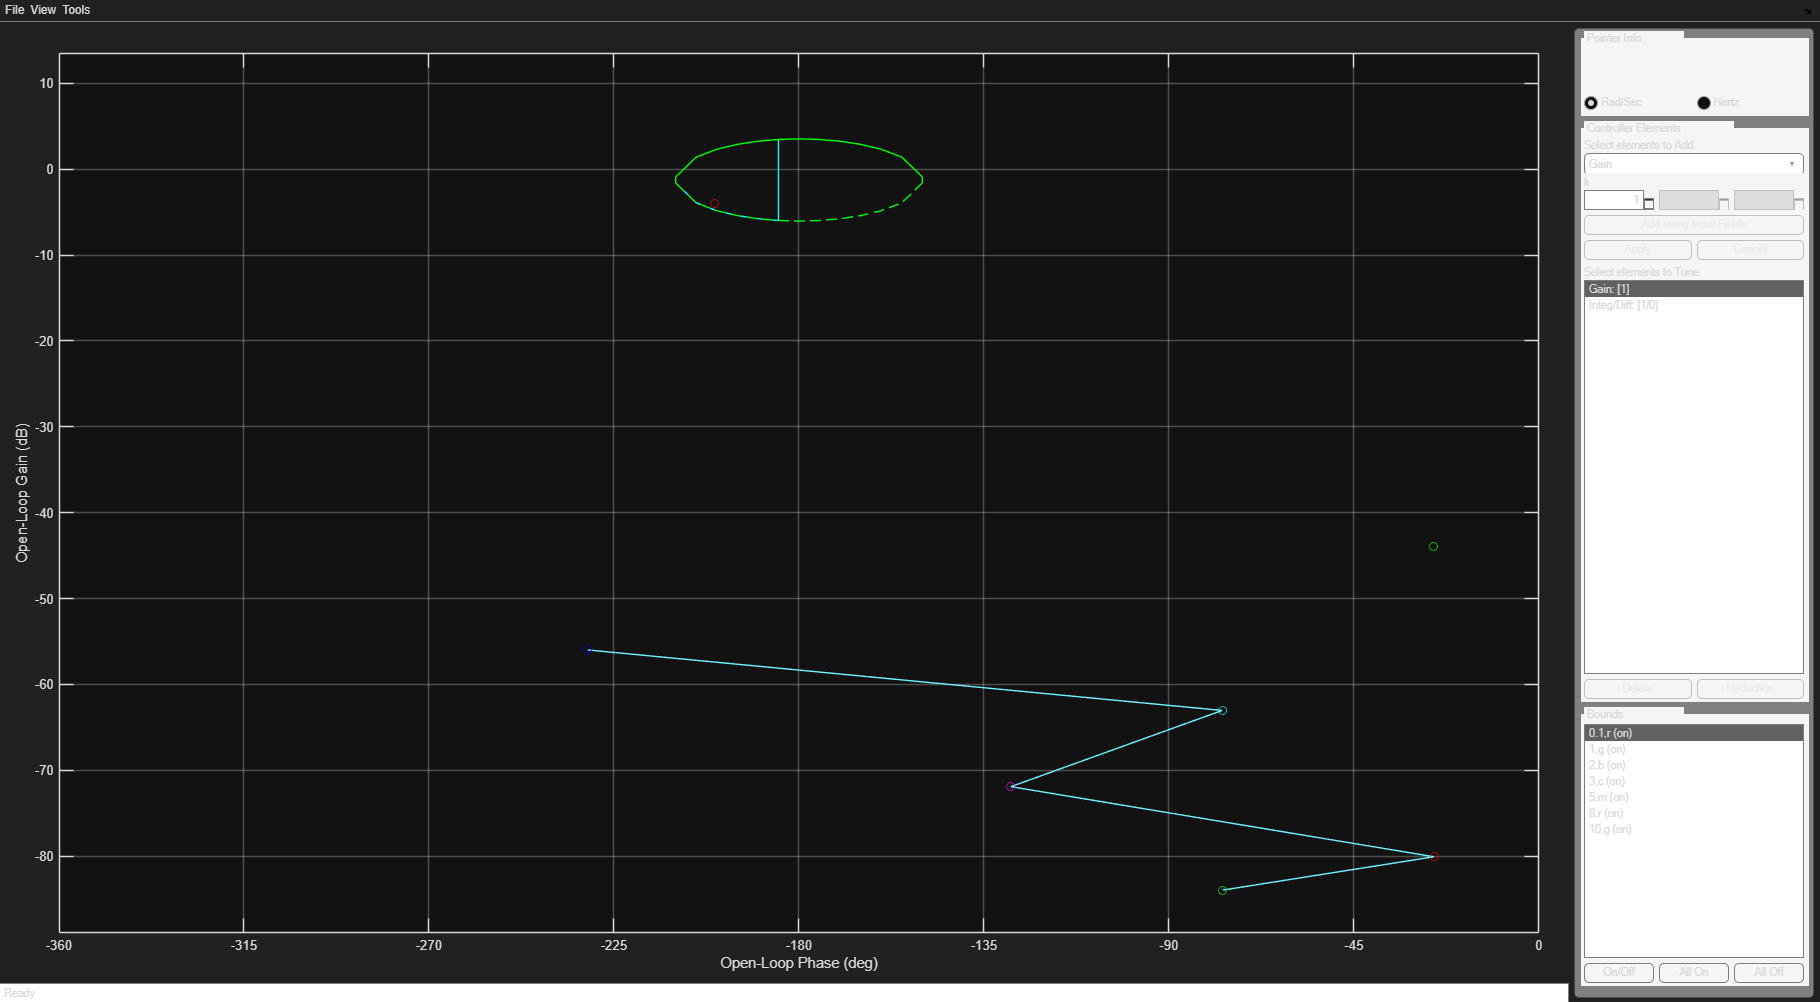


%% Controller Design
% Define the controller G. It is a transfer function with a low-pass filter and a zero-pole structure.
G = 1/s;  

% 'lpshape' likely plots or analyses the low-pass shape of the frequency response
% with the given bounds, the first plant model (P(1,1,1)), and the controller G.
lpshape(w, bnd, P(1,1,1), G);


%% Pre-filter Design
% Define the pre-filter transfer function 'F' which shapes the frequency response before the main controller.

